## Homework 5 - Bioheat Solution

## Base Case - I

clear; close all

uI = readmatrix("xI.dat");
uI = uI(2:end);

nodes = readmatrix("npeltr4.dat");
xNodes = nodes(:, 2);
yNodes = nodes(:, 3);
elemsJunk = readmatrix("epeltr4.dat");
elems = elemsJunk(:, 2:6);

Vec = zeros(size(elems,1),2);

%Triangulate existing Mesh
[elemsTri, elemsTriMat] = meshProb5(elems);

%%Find tumor elements
tumorElem = elemsTri(elemsTriMat==8, :);
tumorNode = unique(tumorElem);
tumorxNodes = xNodes(tumorNode);
tumoryNodes = yNodes(tumorNode);
tumoruI = uI(tumorNode);
tumorVec = zeros(size(tumorElem, 1), 2);

***TriMesh Plot***

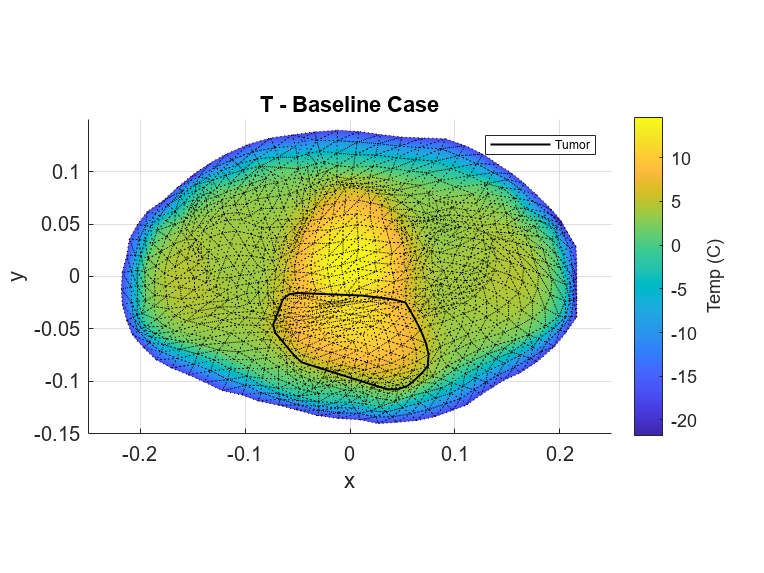

figure;
[h] = Plot2dTriMesh(xNodes, yNodes, elemsTri, uI);
k = convhull(tumorxNodes, tumoryNodes);
plot(tumorxNodes(k), tumoryNodes(k), 'k', 'LineWidth',1);
xlim([-0.25 0.25])
ylim([-0.15 0.15])
clim([ min(uI(:)) max(uI(:)) ]);
c = colorbar;
c.Label.String = 'Temp (C)';
title("T - Baseline Case")
legend('', 'Tumor', 'FontSize', 6)


exportgraphics(gcf, "SteadyState.png", 'Resolution', 300)

***Contour Plot***

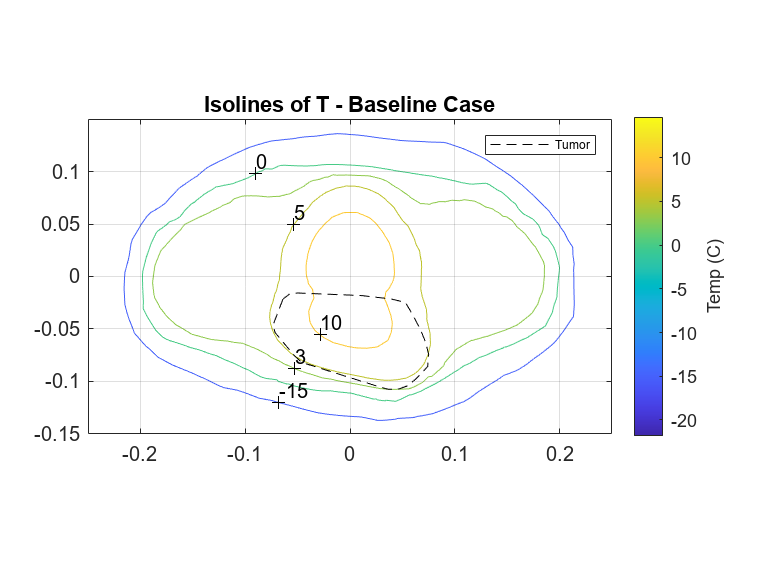

N = 1000;                                                 % Number Of Points Desired
xv = linspace(min(xNodes), max(xNodes), N);
yv = linspace(min(yNodes), max(yNodes), N);
[X,Y] = ndgrid(xv, yv);
Z = griddata(xNodes, yNodes, uI, X, Y);
figure
[C, h] = contour(X, Y, Z, [3 5, 10 0 -15]);
hold on
plot(tumorxNodes(k), tumoryNodes(k), 'k--', 'LineWidth',0.5)
clabel(C)
axis('equal')
grid on
clim([ min(uI(:)) max(uI(:)) ]);
c = colorbar;
c.Label.String = 'Temp (C)';
xlim([-0.25 0.25])
ylim([-0.15 0.15])
title("Isolines of T - Baseline Case")
legend('', 'Tumor', 'FontSize', 6)

exportgraphics(gcf, "SteadyStateContour.png", 'Resolution', 300)

## Case II - Blood Flow in Bladder

uII = readmatrix("xII.dat");
uII = uII(2:end);

***TriMesh Plot***

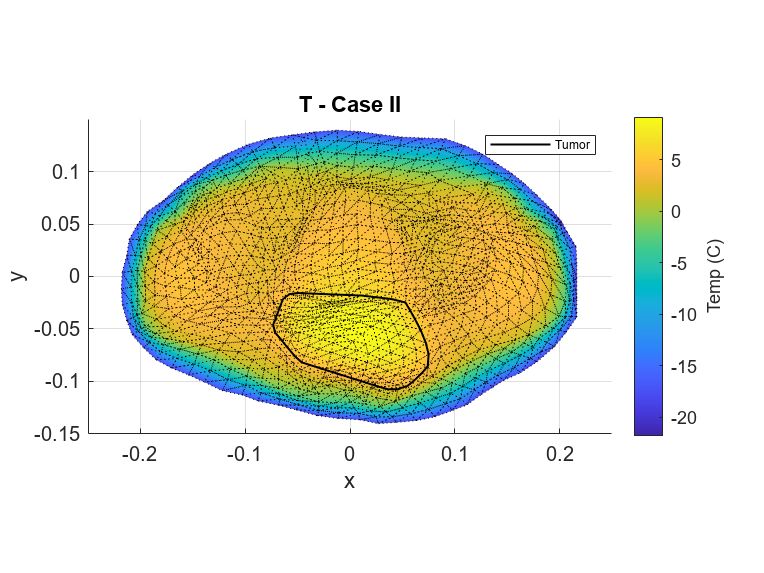

figure;
[h] = Plot2dTriMesh(xNodes, yNodes, elemsTri, uII);
k = convhull(tumorxNodes, tumoryNodes);
plot(tumorxNodes(k), tumoryNodes(k), 'k', 'LineWidth',1);
xlim([-0.25 0.25])
ylim([-0.15 0.15])
clim([ min(uII(:)) max(uII(:)) ]);
c = colorbar;
c.Label.String = 'Temp (C)';
title("T - Case II")
legend('', 'Tumor', 'FontSize', 6)


exportgraphics(gcf, "SteadyStateII.png", 'Resolution', 300)

***Contour Plot***

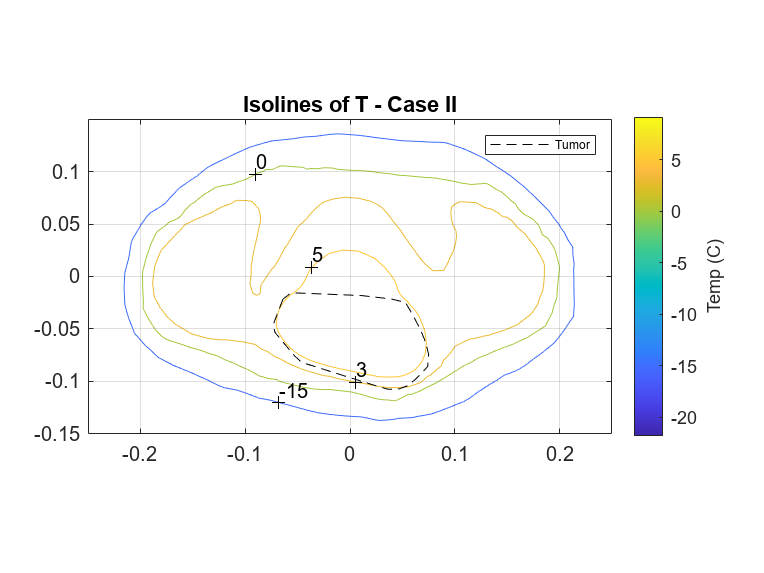

N = 1000;                                                 % Number Of Points Desired
xv = linspace(min(xNodes), max(xNodes), N);
yv = linspace(min(yNodes), max(yNodes), N);
[X,Y] = ndgrid(xv, yv);
Z = griddata(xNodes, yNodes, uII, X, Y);
figure
[C, h] = contour(X, Y, Z, [3 5, 10 0 -15]);
hold on
plot(tumorxNodes(k), tumoryNodes(k), 'k--', 'LineWidth',0.5)
clabel(C)
axis('equal')
grid on
clim([ min(uII(:)) max(uII(:)) ]);
c = colorbar;
c.Label.String = 'Temp (C)';
xlim([-0.25 0.25])
ylim([-0.15 0.15])
title("Isolines of T - Case II")
legend('', 'Tumor', 'FontSize', 6)

exportgraphics(gcf, "SteadyStateContourII.png", 'Resolution', 300)

## Comparison

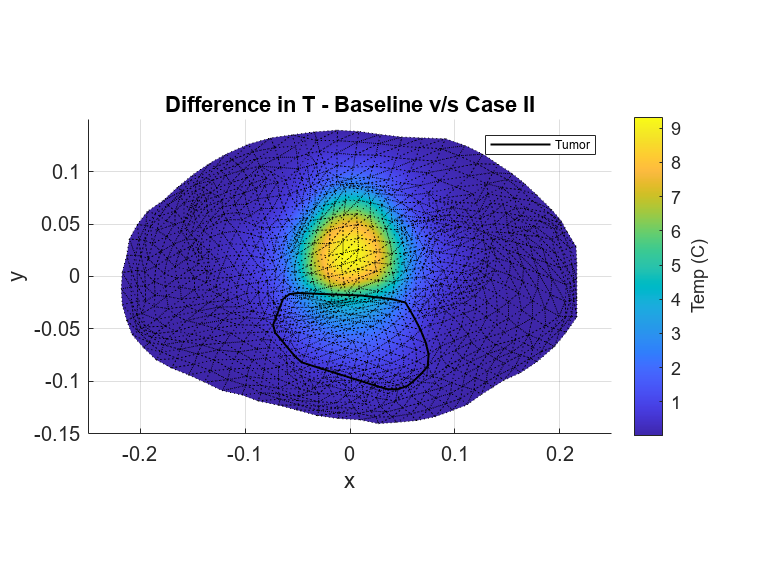

uDiff = uI - uII;
figure;
[h] = Plot2dTriMesh(xNodes, yNodes, elemsTri, uDiff);
k = convhull(tumorxNodes, tumoryNodes);
plot(tumorxNodes(k), tumoryNodes(k), 'k', 'LineWidth',1);
xlim([-0.25 0.25])
ylim([-0.15 0.15])
clim([ min(uDiff(:)) max(uDiff(:)) ]);
c = colorbar;
c.Label.String = 'Temp (C)';
title("Difference in T - Baseline v/s Case II")
legend('', 'Tumor', 'FontSize', 6)

exportgraphics(gcf, "SteadyStateDifference.png", 'Resolution', 300)